# CW Laser Tuning Technique

## Microresonator parameters

ring_parameters = dictionary();
ring_parameters("N") = 511; % Number of modes. It must be odd!
ring_parameters("n0") = 2.4; % Refractive index
ring_parameters("n2") = 2.4e-19; % Nonlinear reftactive index [m^2/W]
ring_parameters("FSR") = 100e9; % Free Spectral Range [Hz]
ring_parameters("lambda0") = 1553.4e-9; % CW pump wavelength [m]
ring_parameters("kappa") = 3e8; % Optical linewidth [Hz]
ring_parameters("eta") = 0.5; % Coupling efficiency
ring_parameters("Veff") = 1e-15; % Effective mode volume [m^3]
ring_parameters("D2") = 2.5e6; % Second order dispersion [Hz]
ring_parameters("Pin") = 2; % Pump power [W]

## `Ring 1 - Forward tuning with no effects (Multi-Soliton generation)`

ring1 = Ring(ring_parameters);

### Simulation parameters

simulation_options_ring1 = dictionary();
simulation_options_ring1("Effects") = "None"; % None or "Thermal" or "Avoided mode crossings"
simulation_options_ring1("Noise") = false; % True or False (White noise)

forward_parameters_ring1 = containers.Map();
forward_parameters_ring1("dseta_start") = -10; % Normalized detuning start
forward_parameters_ring1("dseta_end") = -9; % Normalized detuning end
forward_parameters_ring1("dseta_step") = 0.01; % Tuning step
forward_parameters_ring1("roundtrips_step") = 10; % Roundtrips per tuning step
forward_parameters_ring1("Amu0") = randn(1, ring_parameters("N")) + 1i*randn(1, ring_parameters("N")); % Initial field

### Numerical simulation

[dseta_forward_ring1, amu_forward_ring1] = ring1.numerical_simulation(forward_parameters_ring1, simulation_options_ring1); % Run forward simulation

Forward tuning: 
Progress: 0%
Progress: 1%
Progress: 2%
Progress: 3%
Progress: 4%
Progress: 5%
Progress: 6%
Progress: 7%
Progress: 8%
Progress: 9%
Progress: 10%
Progress: 11%
Progress: 12%
Progress: 13%
Progress: 14%
Progress: 15%
Progress: 16%
Progress: 17%
Progress: 18%
Progress: 19%
Progress: 20%
Progress: 21%
Progress: 22%
Progress: 23%
Progress: 24%
Progress: 25%
Progress: 26%
Progress: 27%
Progress: 28%
Progress: 29%
Progress: 30%
Progress: 31%
Progress: 32%
Progress: 33%
Progress: 34%
Progress: 35%
Progress: 36%
Progress: 37%
Progress: 38%
Progress: 39%
Progress: 40%
Progress: 41%
Progress: 42%
Progress: 43%
Progress: 44%
Progress: 45%
Progress: 46%
Progress: 47%
Progress: 48%
Progress: 49%
Progress: 50%
Progress: 51%
Progress: 52%
Progress: 53%
Progress: 54%
Progress: 55%
Progress: 56%
Progress: 57%
Progress: 58%
Progress: 59%
Progress: 60%
Progress: 61%
Progress: 62%
Progress: 63%
Progress: 64%
Progress: 65%
Progress: 66%
Progress: 67%
Progress: 68%
Progress: 69%
Progress: 70%

### Plot results

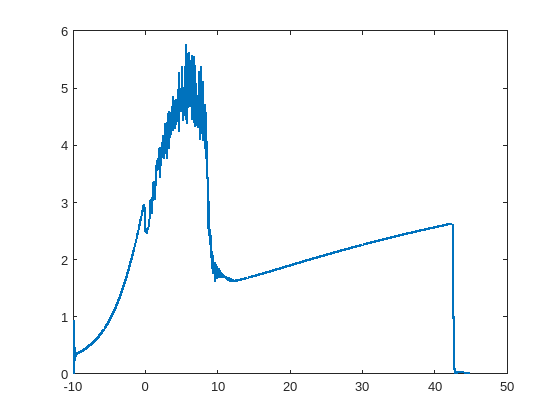

average_intracavity_intensity_frwd = sum(abs(amu_forward_ring1).^2, 2); %Average intracavity intensity forward tuning
plot(dseta_forward_ring1, average_intracavity_intensity_frwd, "LineWidth", 2); %Plot average intracavity intensity vs detuning